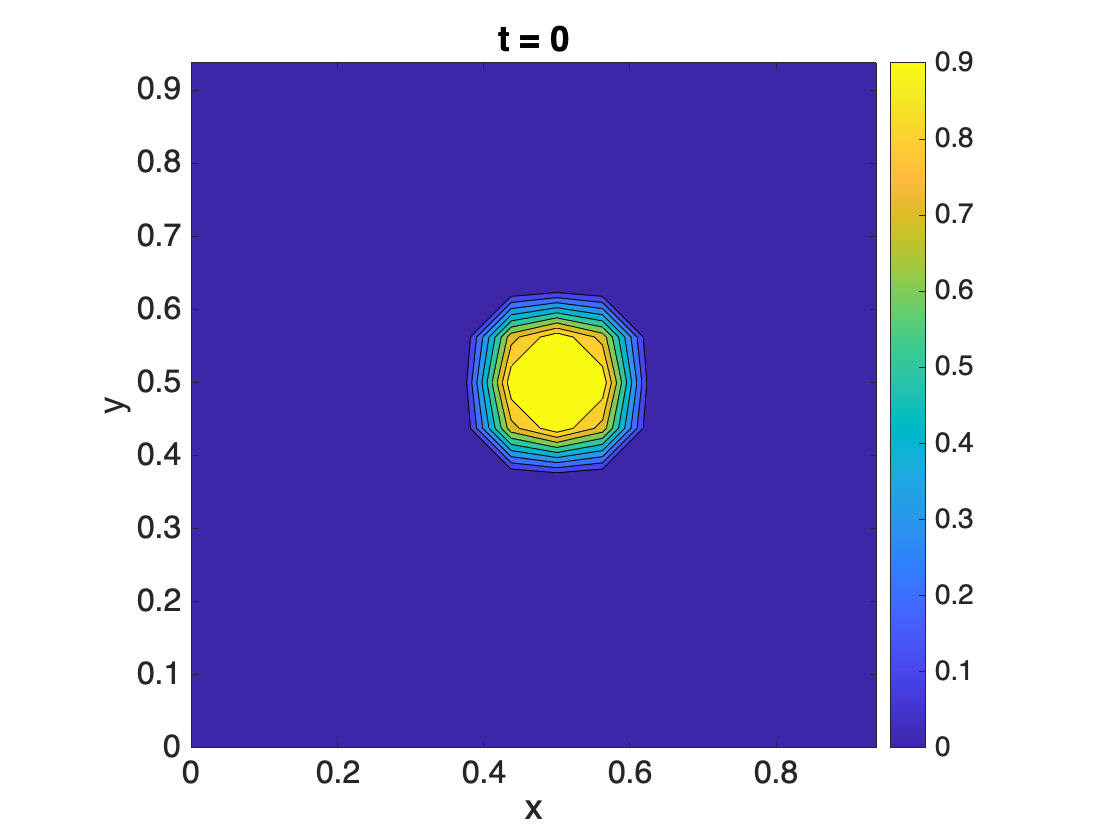

% clear;close;

% Space parameters
    Lx = 1; para.Lx=Lx; Ly=Lx; para.Ly=Ly;
    Nx = 2^4; para.Nx=Nx; Ny=Nx; para.Ny=Nx;
    hx = Lx/Nx;
    hy = Ly/Ny;
    x  = hx*(0:Nx-1);           
    y  = hy*(0:Ny-1);
    [xx,yy] = meshgrid(x,y); 


    k_x = 1i*[0:Nx/2 -Nx/2+1:-1]*(2*pi/Lx);

% Sarah's para
    h=hx;
    h2=h^2;
    gam = 8 * h / (2 * sqrt(2) * atanh(0.9)); % gam is our epsilon
    max_it=100;

% Initial data - by importing
    % phi0 = readmatrix('128_100_phi.csv'); % corresponds to C simulation
   
% Checking the imaginary part of Fourier coefficients of initial data
    % norm(imag(fft2_filtered(phi0)))
    % norm(imag(fft(phi0(1,:))))
    % norm(imag(fft(phi0(end,:))))
    % norm(imag(fft(phi0(:,1))))
    % norm(imag(fft(phi0(:,end))))

% Filtering out the initial data
    % phi0=ifft2(real(fft2(phi0)));

    % figure;
    % contourf(x,y,phi0); colorbar; axis square

    % figure;
    % err=phi0-ifft2(real(fft2(phi0)));
    % contourf(x,y,err); colorbar; axis square

% Initial data - by function
    R = sqrt((xx-0.5).^2 + (yy-0.5).^2);
    R0 = 0.1;
    eps_c = 0.01; 
    psi0 = 0.5 * (1 + tanh((R0 - R)/(2*eps_c)));

    % phi0 = 0.05*sin(xx).*sin(yy); para.phi0=phi0;
    % phi0 = 0.05*sin(x)'.*sin(y); para.phi0=phi0;
    % r0 = r0_fun(phi0); para.r0=r0;
    
    % C_cond=10;
    % C_ref =10;
    % psi0=psi0 * C_ref/C_cond;

    phi0=2*psi0-1;    % psi0=(phi0+1)/2;
    para.phi0=phi0;

% Plot initial
    figure
    contourf(x,y,psi0); colorbar; axis square
    %     % contourf(x,y,phi0); colorbar; axis square
    %     % contour(x,y,psi0,[0.3,0.3],'k',LineWidth=1.5); axis square
    set(gca,'FontSize',16);title('t = 0'); xlabel('x'); ylabel('y');


% Interface and energy parameters
    epsilon=gam/2^0; para.epsilon=epsilon;
    C0=0; para.C0=C0;
    M=epsilon^2; para.M=M;
    % M=0.001; para.M=M;

% Relaxation and Stabilization
    para.Beta=0; para.gamma0=0;

% Time parameters
    para.dt=1e-1*h2; dt=para.dt;
    para.dtout=50; dtout=para.dtout;
    para.T=max_it*dt; T=para.T;
    % l=1;
    % l=40;
    % l=80;
    % l=300;
    % l=500;
    % para.T=l*dtout*dt; T=para.T;



%% CN Solver (Phi collected every dtout results)
    tic;[phi,~,E,~,Phi,O]=CH2d_SAV_CN(para);toc;

Elapsed time is 0.106864 seconds.


    psi=(phi+1)/2; Psi=(Phi+1)/2;
    figure; contourf(x,y,psi); colorbar; axis square



    % f(phi0)
    % C0
    % sqrt(hx*hy*sum(sum(f(phi0))) + C0)
    % sum(sum(1/2*phi0.*(-Lap(phi0))))
    % r0^2
    % sum(sum(1/2*phi0.*(-Lap(phi0))))+r0^2
    % hx*hy*sum(sum(1/2*phi0.*(-Lap(phi0))))+r0^2
    %     D(1) = (r0-sqrt(hx*hy*sum(sum(f(phi0)))))/sqrt(hx*hy*sum(sum(f(phi0))))
    %     imag(fft2(phi0))
    %     norm(imag(fft2(phi0)))
    % O(1) = norm(imag(fft2(phi0)))

phi0+dt/2*M*Lap(df(phi0))
    A_inv_CN(phi0+dt/2*M*Lap(df(phi0)))


    % phi0+dt/2*M*Lap(df(phi0))    
    % phi_bar = A_inv_CN(phi0+dt/2*M*Lap(df(phi0)))
        % phi_bar = A_inv_CN(phi1+dt/2*Lap(df(phi1)));
        % phi_bar = 1/2*(3*phi1-phi0);
        
        % Step 1
        % b = b_fun(phi_bar)
    epsilon = para.epsilon;
    C0 = para.C0;
    M = para.M;
    gamma0 = para.gamma0;
    Beta = para.Beta;

    bphi0 = fft2_filtered(b.*phi0)

bphi0 =  -376.3866  390.6269 -311.0313   50.7476  124.1309  -83.6276  -20.5225   88.7221 -118.5947   88.7221  -20.5225  -83.6276  124.1309   50.7476 -311.0313  390.6269
  390.6269 -381.9733  264.2863  -13.4029 -124.1476   72.2957   24.7405  -84.6380  110.6866  -84.6380   24.7405   72.2957 -124.1476  -13.4029  264.2863 -381.9733
 -311.0313  264.2863 -110.6500  -66.8858  111.8120  -42.0246  -32.9480   70.9392  -87.1481   70.9392  -32.9480  -42.0246  111.8120  -66.8858 -110.6500  264.2863
   50.7476  -13.4029  -66.8858  108.6139  -71.7822    5.7590   34.5756  -44.9636   49.2805  -44.9636   34.5756    5.7590  -71.7822  108.6139  -66.8858  -13.4029
  124.1309 -124.1476  111.8120  -71.7822   18.0910   17.0582  -20.0722    6.4613   -0.9318    6.4613  -20.0722   17.0582   18.0910  -71.7822  111.8120 -124.1476
  -83.6276   72.2957  -42.0246    5.7590   17.0582  -13.5202  -11.7666   39.8337  -50.9609   39.8337  -11.7666  -13.5202   17.0582    5.7590  -42.0246   72.2957
  -20.5225   24.7405  -32.

    bphi0 = hx*hy*bphi0(1,1)

bphi0 = -1.4703


    %r explicit (r multiplied)
    E1 = fft2_filtered(f(phi0));
    g = phi0 - dt/2*M*Lap(Lap(phi0)) + dt/2*gamma0/epsilon^2*M*Lap(phi0) ...
    + dt*M.*Lap(b)*(r0-1/4*bphi0-1/2*Beta*dt*r0*(r0-sqrt(E1(1,1)*hx*hy+C0)))

g =    -1.0018   -0.9981   -1.0022   -0.9968   -1.0053   -0.9855   -1.0766   -0.6621   -0.5051   -0.6621   -1.0766   -0.9855   -1.0053   -0.9968   -1.0022   -0.9981
   -0.9981   -1.0020   -0.9976   -1.0032   -0.9942   -1.0151   -0.9197   -1.3553   -1.5170   -1.3553   -0.9197   -1.0151   -0.9942   -1.0032   -0.9976   -1.0020
   -1.0022   -0.9976   -1.0028   -0.9960   -1.0070   -0.9830   -1.0940   -0.5865   -0.4109   -0.5865   -1.0940   -0.9830   -1.0070   -0.9960   -1.0028   -0.9976
   -0.9968   -1.0032   -0.9960   -1.0057   -0.9918   -1.0253   -0.8820   -1.5526   -1.7508   -1.5526   -0.8820   -1.0253   -0.9918   -1.0057   -0.9960   -1.0032
   -1.0053   -0.9942   -1.0070   -0.9918   -1.0174   -0.9643   -1.1805   -0.1239    0.0910   -0.1239   -1.1805   -0.9643   -1.0174   -0.9918   -1.0070   -0.9942
   -0.9855   -1.0151   -0.9830   -1.0253   -0.9643   -1.0749   -0.6027   -2.7849   -2.9178   -2.7849   -0.6027   -1.0749   -0.9643   -1.0253   -0.9830   -1.0151
   -1.0766   -0.9197   -1.0940


    % phi0 - dt/2*M*Lap(Lap(phi0))
    % dt/2*gamma0/epsilon^2*M*Lap(phi0)
    % dt*M.*Lap(b)*(r0-1/4*bphi0-1/2*Beta*dt*r0*(r0-sqrt(E1(1,1)*hx*hy+C0)))


        AiLb = A_inv_CN(M*Lap(b))

AiLb =     0.0107    0.0964    0.3010    0.4805    0.4469    0.1082   -0.3997   -0.5798   -0.4759   -0.5798   -0.3997    0.1082    0.4469    0.4805    0.3010    0.0964
    0.0964    0.1638    0.2709    0.1827   -0.2857   -1.0795   -1.9464   -2.8475   -3.3553   -2.8475   -1.9464   -1.0795   -0.2857    0.1827    0.2709    0.1638
    0.3010    0.2709   -0.0241   -0.9180   -2.3042   -3.4443   -3.6320   -2.8082   -2.1622   -2.8082   -3.6320   -3.4443   -2.3042   -0.9180   -0.0241    0.2709
    0.4805    0.1827   -0.9180   -2.7255   -3.6992   -1.6592    3.3443    8.0570    9.7664    8.0570    3.3443   -1.6592   -3.6992   -2.7255   -0.9180    0.1827
    0.4469   -0.2857   -2.3042   -3.6992    0.0439   11.0090   22.9374   28.8286   29.9161   28.8286   22.9374   11.0090    0.0439   -3.6992   -2.3042   -0.2857
    0.1082   -1.0795   -3.4443   -1.6592   11.0090   26.0856   17.4960  -11.2495  -25.5620  -11.2495   17.4960   26.0856   11.0090   -1.6592   -3.4443   -1.0795
   -0.3997   -1.9464   -3.6

        Aig  = A_inv_CN(g)

Aig =    -1.0001   -1.0001   -1.0000   -1.0000   -0.9997   -0.9994   -0.9987   -0.9972   -0.9964   -0.9972   -0.9987   -0.9994   -0.9997   -1.0000   -1.0000   -1.0001
   -1.0001   -1.0000   -1.0000   -0.9998   -0.9994   -0.9991   -0.9991   -1.0003   -1.0011   -1.0003   -0.9991   -0.9991   -0.9994   -0.9998   -1.0000   -1.0000
   -1.0000   -1.0000   -0.9997   -0.9992   -0.9989   -0.9992   -1.0000   -1.0001   -1.0000   -1.0001   -1.0000   -0.9992   -0.9989   -0.9992   -0.9997   -1.0000
   -1.0000   -0.9998   -0.9992   -0.9989   -1.0002   -1.0048   -1.0132   -1.0228   -1.0270   -1.0228   -1.0132   -1.0048   -1.0002   -0.9989   -0.9992   -0.9998
   -0.9997   -0.9994   -0.9989   -1.0002   -1.0074   -1.0234   -1.0413   -1.0496   -1.0506   -1.0496   -1.0413   -1.0234   -1.0074   -1.0002   -0.9989   -0.9994
   -0.9994   -0.9991   -0.9992   -1.0048   -1.0234   -1.0479   -1.0380   -0.9734   -0.9287   -0.9734   -1.0380   -1.0479   -1.0234   -1.0048   -0.9992   -0.9991
   -0.9987   -0.9991   -1.00

        
        gamma = -fft2_filtered(b.*AiLb)

gamma = 1.0e+04 *

    5.3278   -4.4184    2.4262   -0.6096   -0.4294    0.6045    0.0108   -0.9468    1.3987   -0.9468    0.0108    0.6045   -0.4294   -0.6096    2.4262   -4.4184
   -4.4184    3.6527   -1.9678    0.4183    0.4692   -0.5806   -0.0356    0.9324   -1.3593    0.9324   -0.0356   -0.5806    0.4692    0.4183   -1.9678    3.6527
    2.4262   -1.9678    0.9468    0.0119   -0.5470    0.5060    0.0932   -0.8633    1.2146   -0.8633    0.0932    0.5060   -0.5470    0.0119    0.9468   -1.9678
   -0.6096    0.4183    0.0119   -0.4113    0.5762   -0.3814   -0.1324    0.6756   -0.9047    0.6756   -0.1324   -0.3814    0.5762   -0.4113    0.0119    0.4183
   -0.4294    0.4692   -0.5470    0.5762   -0.4802    0.2359    0.0733   -0.3059    0.3867   -0.3059    0.0733    0.2359   -0.4802    0.5762   -0.5470    0.4692
    0.6045   -0.5806    0.5060   -0.3814    0.2359   -0.1376    0.1512   -0.2483    0.3052   -0.2483    0.1512   -0.1376    0.2359   -0.3814    0.5060   -0.5806
    0.0108   -0

        gamma = gamma(1,1)*hx*hy

gamma = 208.1160


              % Step 2

bphi =    17.3859   51.3272 -103.2292  -15.6978   95.6293  -31.7767  -34.6127   46.3905  -50.2919   46.3905  -34.6127  -31.7767   95.6293  -15.6978 -103.2292   51.3272
   51.3272  -91.2551   91.0168   33.7136  -87.9564   19.3144   38.1120  -42.4463   43.2686  -42.4463   38.1120   19.3144  -87.9564   33.7136   91.0168  -91.2551
 -103.2292   91.0168  -20.9954  -67.6027   57.9690   13.0059  -45.3259   31.5409  -25.0766   31.5409  -45.3259   13.0059   57.9690  -67.6027  -20.9954   91.0168
  -15.6978   33.7136  -67.6027   62.2237   -2.8733  -49.4098   48.7397  -16.6425    3.2341  -16.6425   48.7397  -49.4098   -2.8733   62.2237  -67.6027   33.7136
   95.6293  -87.9564   57.9690   -2.8733  -51.3755   68.5394  -42.2355    2.4485   13.3917    2.4485  -42.2355   68.5394  -51.3755   -2.8733   57.9690  -87.9564
  -31.7767   19.3144   13.0059  -49.4098   68.5394  -58.2160   25.9730    6.5873  -19.1368    6.5873   25.9730  -58.2160   68.5394  -49.4098   13.0059   19.3144
  -34.6127   38.1120  -45.3

        bphi = fft2_filtered(b.*Aig)
        bphi = bphi(1,1)*hx*hy/(1+dt/4*gamma)

bphi = 0.0666


        % Step 3

        phi = dt/4*bphi.*AiLb + Aig

phi =    -1.0001   -1.0001   -1.0000   -1.0000   -0.9997   -0.9994   -0.9988   -0.9972   -0.9964   -0.9972   -0.9988   -0.9994   -0.9997   -1.0000   -1.0000   -1.0001
   -1.0001   -1.0000   -1.0000   -0.9998   -0.9994   -0.9991   -0.9991   -1.0004   -1.0011   -1.0004   -0.9991   -0.9991   -0.9994   -0.9998   -1.0000   -1.0000
   -1.0000   -1.0000   -0.9997   -0.9993   -0.9989   -0.9992   -1.0001   -1.0001   -1.0000   -1.0001   -1.0001   -0.9992   -0.9989   -0.9993   -0.9997   -1.0000
   -1.0000   -0.9998   -0.9993   -0.9989   -1.0002   -1.0048   -1.0132   -1.0227   -1.0269   -1.0227   -1.0132   -1.0048   -1.0002   -0.9989   -0.9993   -0.9998
   -0.9997   -0.9994   -0.9989   -1.0002   -1.0074   -1.0233   -1.0411   -1.0494   -1.0504   -1.0494   -1.0411   -1.0233   -1.0074   -1.0002   -0.9989   -0.9994
   -0.9994   -0.9991   -0.9992   -1.0048   -1.0233   -1.0478   -1.0379   -0.9735   -0.9289   -0.9735   -1.0379   -1.0478   -1.0233   -1.0048   -0.9992   -0.9991
   -0.9988   -0.9991   -1.00

        r   = r_fun(phi,phi0,r0,b)

r = 1.1798

        % r   = r_fun(phi,phi1,r1,b);
    
%% update phi0, phi1, r1
        phi0 = phi;
        r0   = r;
        % phi0 = phi1;
        % phi1 = phi;
        % r1  = r;

        if mod(nt,dtout)==0
            ll = nt/dtout;
            tt = Nx*ll+1 : Nx*(ll+1);
            Phi(tt,1:Ny)=phi;
        end

Unrecognized function or variable 'nt'.


                %% First Order Function Library

function g = g_fun_FO(phi0,r0,b)
global dt hx hy C0 Beta M
    bphi0 = fft2_filtered(b.*phi0);
    bphi0 = hx*hy*bphi0(1,1);

    %r explicit (r multiplied)
    E1 = fft2_filtered(f(phi0));
    g = phi0 + dt.*M*Lap(b)*(r0-1/2*bphi0-Beta*dt*r0*(r0-sqrt(E1(1,1)*hx*hy+C0))); 
end

function Ai = A_inv_FO(phi)
global dt k2 k4 gamma0 epsilon M
    Ai = real(ifft2(fft2_filtered(phi)./(1+dt*M*k4-dt*gamma0/epsilon^2*M*k2)));
end
%% Crank Nicolson Function Library
function g = g_fun_CN(phi0,r0,b)
global dt hx hy gamma0 epsilon Beta C0 M
    bphi0 = fft2_filtered(b.*phi0);
    bphi0 = hx*hy*bphi0(1,1);

    %r explicit (r multiplied)
    E1 = fft2_filtered(f(phi0));
    g = phi0 - dt/2*M*Lap(Lap(phi0)) + dt/2*gamma0/epsilon^2*M*Lap(phi0) ...
    + dt*M.*Lap(b)*(r0-1/4*bphi0-1/2*Beta*dt*r0*(r0-sqrt(E1(1,1)*hx*hy+C0)));
end

function Ai = A_inv_CN(phi)
global dt k2 k4 gamma0 epsilon M
    Ai = real(ifft2(fft2_filtered(phi)./(1+dt/2*M*k4-dt/2*gamma0/epsilon^2*M*k2)));
end


function [phi,r,E,D,Phi,O]=CH2d_SAV_CN(para)
% Solve 2D Cahn Hilliard equaiton
% \phi_t = \Delta \mu
% \mu = \Delta\phi + (\phi^3 - \phi)/epsilon^2
global dt epsilon k2 k4 C0 hx hy Lx Ly gamma0 Beta M

%% Parameters
    T  = para.T;
    dt = para.dt;
    t  = 0;
    Nt = round(T/dt);
    E  = zeros(1,Nt+1);  
    
    Lx = para.Lx;
    Ly = para.Ly;
    Nx= para.Nx;
    Ny= para.Ny;
    hx = Lx/Nx;
    hy = Ly/Ny;
    x = hx*(0:Nx-1);
    y = hy*(0:Ny-1);
    k_x = 1i*[0:Nx/2 -Nx/2+1:-1]*(2*pi/Lx);
    k_y = 1i*[0:Ny/2 -Ny/2+1:-1]*(2*pi/Ly);
    % [kx,ky] = meshgrid(k_x,k_y);
    k_xx = k_x.^2;
    k_yy = k_y.^2;
    [kxx,kyy] = meshgrid(k_xx,k_yy);
    k2 = kxx + kyy;
    % k2 = k_xx+k_yy;
    k4 = k2.^2;
    
    epsilon = para.epsilon;
    C0 = para.C0;
    M = para.M;
    gamma0 = para.gamma0;
    Beta = para.Beta;
    
    phi0 = para.phi0;
    % phi  = phi0;
    % r0 = para.r0;
    r0 = r0_fun(phi0);
    % r  = r0;

    dtout=para.dtout;
    Phi(1:Nx,1:Ny)=phi0;

% Prepare [phi1 r1], the 1st step by FO and CN_pc1st
    % para1 = para; para1.T=dt;
    % [phi1,r1,E,D]  = CH2d_SAV_FO(para1);
    % [phi1,r1,E] = CH1d_SAV_CN_pc1st(para1,phi1);

% Initial modified energy
    E(1)=hx*hy*sum(sum(1/2*phi0.*(-Lap(phi0))))+r0^2;

% Error
    D(1) = (r0-sqrt(hx*hy*sum(sum(f(phi0)))))/sqrt(hx*hy*sum(sum(f(phi0))));
    O(1) = norm(imag(fft2(phi0)));
%% Time iteration
    for nt = 1:Nt
    % for nt = 2:Nt
        t = t+dt;
    
        phi_bar = A_inv_CN(phi0+dt/2*M*Lap(df(phi0)));
        % phi_bar = A_inv_CN(phi1+dt/2*Lap(df(phi1)));
        % phi_bar = 1/2*(3*phi1-phi0);
        
        % Step 1
        b = b_fun(phi_bar);
        
        g = g_fun_CN(phi0,r0,b);
        % g = g_fun_CN(phi1,r1,b);
        
        AiLb = A_inv_CN(M*Lap(b));
        Aig  = A_inv_CN(g);    
        
        gamma = -fft2_filtered(b.*AiLb);
        gamma = gamma(1,1)*hx*hy;
        
        % Step 2      
        bphi = fft2_filtered(b.*Aig);
        bphi = bphi(1,1)*hx*hy/(1+dt/4*gamma);
        
        % Step 3
        phi = dt/4*bphi.*AiLb + Aig;
        r   = r_fun(phi,phi0,r0,b);
        % r   = r_fun(phi,phi1,r1,b);
    
%% update phi0, phi1, r1
        phi0 = phi;
        r0   = r;
        % phi0 = phi1;
        % phi1 = phi;
        % r1  = r;

        if mod(nt,dtout)==0
            ll = nt/dtout;
            tt = Nx*ll+1 : Nx*(ll+1);
            Phi(tt,1:Ny)=phi;
        end

%% Modified energy
        E(1+nt)=hx*hy*sum(sum(1/2*phi.*(-Lap(phi))))+r^2;
% Error
        D(1+nt)=(r-sqrt(hx*hy*sum(sum(f(phi)))))/sqrt(hx*hy*sum(sum(f(phi))));
        O(1+nt) = norm(imag(fft2(phi)));
    end

end



%% General Function Library
function r0 = r0_fun(phi0)
global hx hy C0
    r0 = sqrt(hx*hy*sum(sum(f(phi0))) + C0);
end

function r = r_fun(phi,phi0,r0,b)
global hx hy C0 Beta dt
    bphi0 = fft2_filtered(b.*phi0);
    bphi0 = hx*hy*bphi0(1,1);
    bphi  = fft2_filtered(b.*phi);
    bphi  = hx*hy*bphi(1,1);

    E1 = fft2_filtered(f(phi0));
    r = r0 + 1/2*(bphi-bphi0)-Beta*dt*r0*(r0-sqrt(E1(1,1)*hx*hy+C0)); %r explicit (r multiplied)
end

function b = b_fun(phi)
global C0 hx hy
    E1 = fft2_filtered(f(phi));
    b = df(phi)./sqrt(E1(1,1)*hx*hy+C0);
end

function Lphi=Lap(phi)
global k2
    Lphi=real(ifft2((k2.*fft2_filtered(phi))));
end

% function Dphi = Diff(phi)
% global k
%     Dphi=real(ifft((k.*fft(phi))));
% end

function fphi = f(phi)
global epsilon gamma0
    % fphi = (phi.^2-1-gamma0).^2/(4*epsilon^2);
    a=0.5;
    psi=(phi+1)/2;
    fphi = 4*psi.^2.*(6*a-4*(1+a)*psi+3*psi.^2)/(3*epsilon^2);
end

function dfphi = df(phi)
global epsilon gamma0
    % dfphi = (phi.^3-(1+gamma0)*phi)/epsilon^2;

    a=0.5;
    dpsidphi=1/2;
    psi=(phi+1)/2;
    dfphi = 16*(1-psi).*(a-psi).*psi/epsilon^2 * dpsidphi;
end

function y=fft2_filtered(x)
    y=real(fft2(x));
end


